%% Robot Config
alpha = 1/5;
d = 0.235; % m

U_RANGE = [0 3.2];
T_RANGE = U_RANGE ./ alpha;
N = 50;

us = linspace(U_RANGE(1), U_RANGE(2), N)';
ts = us ./ alpha;

equations

$$r = \left(\begin{array}{ccc} \frac{198\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{125} & -\frac{99\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{25} & 0 \end{array}\right)$$

$$v = \left(\begin{array}{ccc} -\frac{5247\,\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{6250} & -\frac{99\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)}{125} & 0 \end{array}\right)$$

$$speed = \sqrt{\frac{27531009\,{\left|\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)\right|}^{2}}{39062500}+\frac{9801\,{\left|\cos\left(\frac{t}{5}+\frac{7}{5}\right)\right|}^{2}}{15625}}$$

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}^{2}} \end{array}$$

$$dT\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sqrt{2}\,\left(96725\,\cos\left(\frac{13\,t}{100}+\frac{91}{100}\right)+140450\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)+43725\,\cos\left(\frac{93\,t}{100}+\frac{651}{100}\right)\right)}{2\,\sigma_{1}} & \frac{\sqrt{2}\,\left(112360\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)+205057\,\sin\left(\frac{43\,t}{50}+\frac{301}{50}\right)+92697\,\sin\left(\frac{63\,t}{50}+\frac{441}{50}\right)\right)}{4\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(2500\,\cos\left(\frac{2\,t}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{50}+\frac{371}{50}\right)+5309\right)}^{3/2} \end{array}$$

$$omega = \left(\begin{array}{ccc} 0 & 0 & -\frac{9672500\,\cos\left(\frac{7\,t}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,t}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,t}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,t}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,t}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,t}{100}+\frac{1253}{100}\right)}{4\,{\left(2500\,\cos\left(\frac{2\,t}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{50}+\frac{371}{50}\right)+5309\right)}^{2}} \end{array}\right)$$

$$rotation\_speed = -\frac{9672500\,\cos\left(\frac{7\,t}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,t}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,t}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,t}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,t}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,t}{100}+\frac{1253}{100}\right)}{4\,{\left(2500\,\cos\left(\frac{2\,t}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{50}+\frac{371}{50}\right)+5309\right)}^{2}}$$

$$v\_l = \frac{47\,\left(9672500\,\cos\left(\frac{7\,t}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,t}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,t}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,t}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,t}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,t}{100}+\frac{1253}{100}\right)\right)}{1600\,{\left(2500\,\cos\left(\frac{2\,t}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{50}+\frac{371}{50}\right)+5309\right)}^{2}}+\frac{99\,\sqrt{2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}^{2}}}{6250}$$

$$v\_r = \frac{99\,\sqrt{2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}^{2}}}{6250}-\frac{47\,\left(9672500\,\cos\left(\frac{7\,t}{100}+\frac{49}{100}\right)+40540601\,\cos\left(\frac{33\,t}{100}+\frac{231}{100}\right)+17375361\,\cos\left(\frac{73\,t}{100}+\frac{511}{100}\right)+4372500\,\cos\left(\frac{113\,t}{100}+\frac{791}{100}\right)-10868021\,\cos\left(\frac{139\,t}{100}+\frac{973}{100}\right)-4912941\,\cos\left(\frac{179\,t}{100}+\frac{1253}{100}\right)\right)}{1600\,{\left(2500\,\cos\left(\frac{2\,t}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{50}+\frac{371}{50}\right)+5309\right)}^{2}}$$

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2\,\left(96725\,\sigma_{6}+140450\,\sigma_{5}+43725\,\sigma_{4}\right)}{\sigma_{1}} & \frac{112360\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)+205057\,\sigma_{3}+92697\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=53\,\sqrt{2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}+2809\,{\left(40\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{63\,t}{50}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,t}{50}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{93\,t}{100}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,t}{100}+\frac{91}{100}\right) \end{array}$$

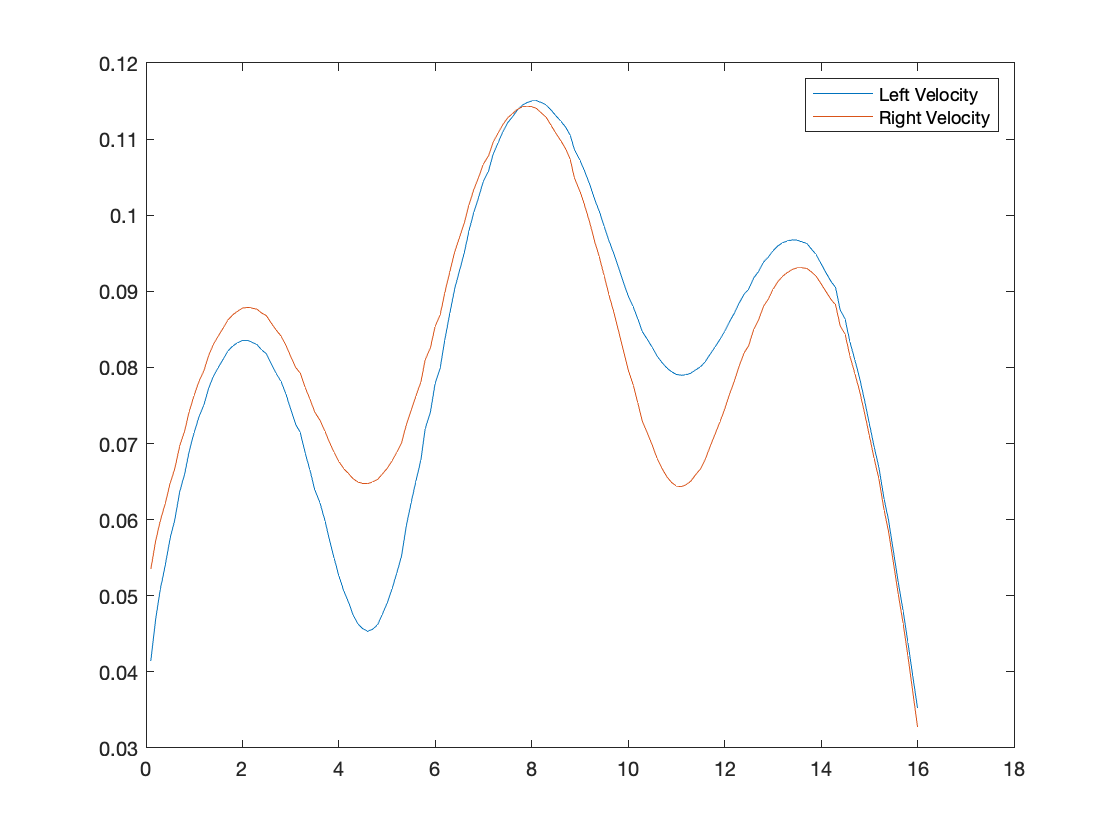

clf; load("encoder_data.mat");

enc_dt = diff(enc_t);
enc_dl = diff(enc_l);    
enc_dr = diff(enc_r);
plot(enc_t(2:end), enc_dl); hold on;
plot(enc_t(2:end), enc_dr);
legend("Left Velocity", "Right Velocity")

## Exercise 21.1

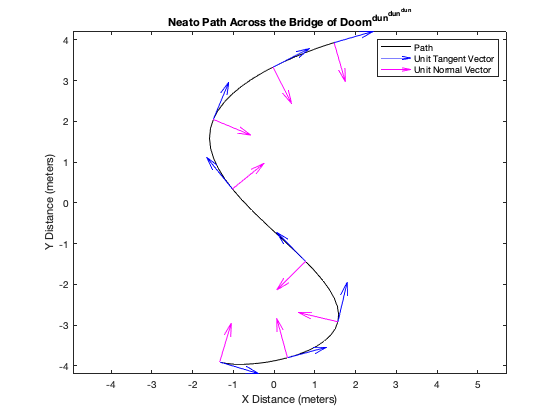

figure(1); clf;

points = double(subs(r, t, ts));
plot(points(:, 1), points(:, 2), 'k-'); axis equal; hold on;

ts_for_arrows = linspace(T_RANGE(1), T_RANGE(2), N / 6)';
start_points_for_arrows = double(subs(r, t, ts_for_arrows));
that_end_points = double(subs(T_hat, t, ts_for_arrows));
nhat_end_points = double(subs(N_hat, t, ts_for_arrows));
quiver(start_points_for_arrows(:, 1), start_points_for_arrows(:, 2), that_end_points(:, 1), that_end_points(:, 2), "off", 'filled', 'b');
quiver(start_points_for_arrows(:, 1), start_points_for_arrows(:, 2), nhat_end_points(:, 1), nhat_end_points(:, 2), "off", "filled", 'm');
legend("Path", "Unit Tangent Vector", "Unit Normal Vector")
xlabel("X Distance (meters)");
ylabel("Y Distance (meters)");
title("Neato Path Across the Bridge of Doom^{dun^{dun^{dun}}}")

## Exercise 21.2

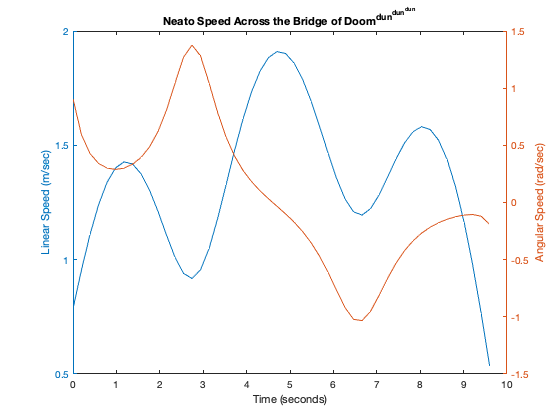

speeds = double(subs(speed, t, ts));
rot_speeds = double(subs(rotation_speed, t, ts));
figure(2); clf;
yyaxis left;
plot(ts, speeds);
ylabel("Linear Speed (m/sec)");
yyaxis right;
plot(ts, rot_speeds);
%legend("Linear Speed", "Angular Speed")
xlabel("Time (seconds)");
ylabel("Angular Speed (rad/sec)");
title("Neato Speed Across the Bridge of Doom^{dun^{dun^{dun}}}")

## Exercise 21.3

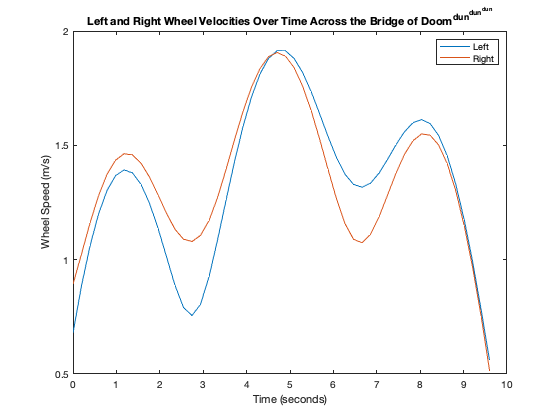

Unrecognized function or variable 'dridriv'.

figure(3); clf;
v_ls = double(subs(v_l, t, ts));
v_rs = double(subs(v_r, t, ts));
plot(ts, v_ls); hold on;
plot(ts, v_rs);

title("Left and Right Wheel Velocities Over Time Across the Bridge of Doom^{dun^{dun^{dun}}}")
xlabel("Time (seconds)");
ylabel("Wheel Speed (m/s)");
legend("Left", "Right");